gen_nodes1 =     1.0000    1.0000
    1.0000    1.0400
    1.0800    1.0400
    1.0800    1.0000


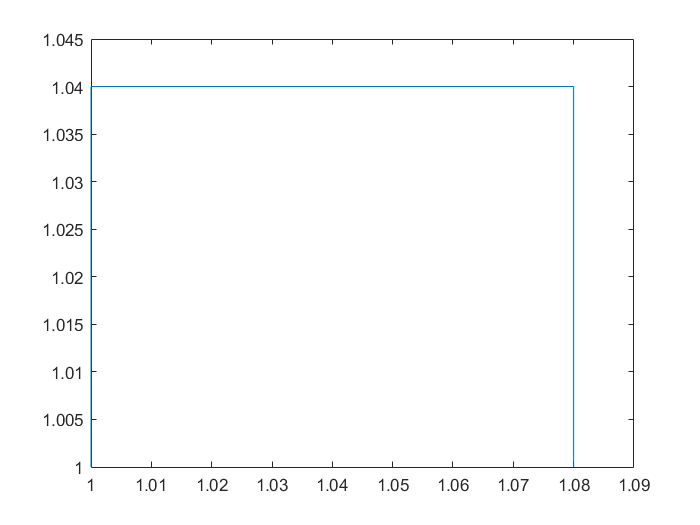

% MESHING
clear
% Section 1
gen_nodes1 = [0,0;0,0.04;0.08,0.04;0.08,0];

x_side = max(gen_nodes1(:,1))-min(gen_nodes1(:,1));

x_side = 0.0800

y_side = max(gen_nodes1(:,2))-min(gen_nodes1(:,2));

y_side = 0.0400

gen_area1 = x_side*y_side;

gen_area1 = 0.0032

syms s real
N = 10;
eqn1 = N*s^2 == gen_area1;
solu = solve(eqn1,s);
solu = double(solu);
solu = solu(solu>0)

solu = 0.0179

ax = x_side/solu;

ax = 4.4721

by = y_side/solu;

by = 2.2361

A = ceil(ax);

A = 5

B = ceil(by);

B = 3

el_sidex = x_side/A;

el_sidex = 0.0160

el_sidey = y_side/B;

el_sidey = 0.0133

area2 = 0.0032

x_vert = min(gen_nodes1(:,1)):el_sidex:max(gen_nodes1(:,1));

x_vert =     1.0000    1.0160    1.0320    1.0480    1.0640    1.0800


y_vert = min(gen_nodes1(:,2)):el_sidey:max(gen_nodes1(:,2));

y_vert =     1.0000    1.0133    1.0267    1.0400


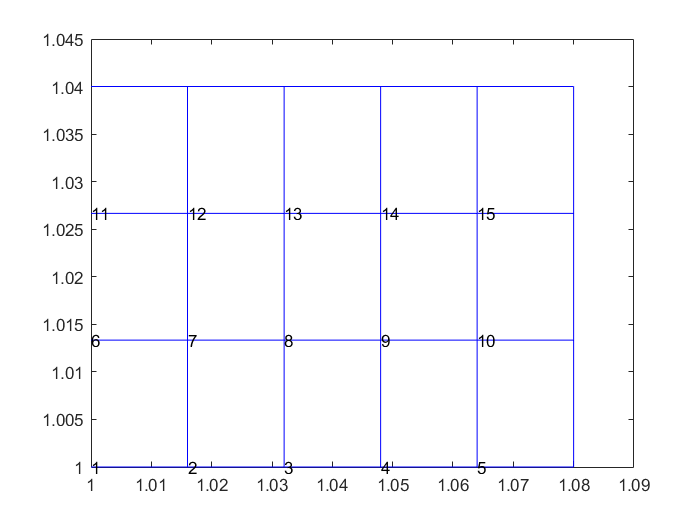

% Obtain node coordinates anticlockwise for element
for j = 1:1:(B+1)
    for i = 1:1:(A+1)
        
        cord=(A+1)*(j-1)+i;    
        Nodes(cord,1)=x_vert(i);
        Nodes(cord,2)=y_vert(j);  
        
    end
end

% Determine each node of each element
for j = 1:1:B
    for i = 1:1:A
        
        pos=A*(j-1)+i;    
        posNode(pos,1)=(A+1)*(j-1)+i;
        posNode(pos,2)=(A+1)*(j-1)+i+1;
        posNode(pos,3)=(A+1)*j+i+1;
        posNode(pos,4)=(A+1)*j+i;
        
    end
end

% Recover coordinates of each node in each element
for i = 1:A*B
    
    Ele_Nodes(1:4,i*2-1:i*2) = Nodes(posNode(i,:),:);
    
end

figure
for ele = 1:A*B
    plot(Ele_Nodes(:,ele*2-1),Ele_Nodes(:,ele*2),'b-')
    text(Ele_Nodes(1,ele*2-1),Ele_Nodes(1,ele*2),num2str(ele))
    hold on
end